# Inicialização de Variáveis

dbstop if error
warning('off','all')
obj = RadarSimulator;

ans =   RadarSimulator with properties:

                      antenna_rpm: 12
                    beam_aperture: 3
                                c: 300000000
                           dcycle: 1.0000e-03
                             dSNR: 0
                             dSCR: 10
                             dvdt: 0
                               fp: 3.0000e+09
                               Gt: 1
                               Gr: 1
                                L: 6
                            Nofig: 0
                               Pt: 1
                               Pr: 1
                                R: 60000
                            Sigma: 1
                      SimDuration: 2
                               Tp: 2.0000e-06
                              V_0: 0
                     acceleration: 0
           npulses_per_prediction: 10
                       Integrator: 'noncoherent'
                    

simtime = 3; % seconds
obj.npulses_per_prediction = 5;
SCR = 0:2.5:20; % db
SNR = 100;
Pd_ncoh = zeros(length(SCR), 1);
Pd_coh = zeros(length(SCR), 1);
Pd_none = zeros(length(SCR), 1);

pfa_ncoh = zeros(length(SCR), 1);
pfa_coh = zeros(length(SCR), 1);
pfa_none = zeros(length(SCR), 1);

thresh_ncoh = zeros(length(obj.rangegates),length(SCR));
thresh_coh = zeros(length(obj.rangegates),length(SCR));
thresh_none = zeros(length(obj.rangegates),length(SCR));

signal_cfar_ncoh = zeros(length(obj.rangegates),length(SCR));
signal_cfar_coh = zeros(length(obj.rangegates),length(SCR));
signal_cfar_none = zeros(length(obj.rangegates),length(SCR));

rangegates =obj.rangegates;

distrib = ["weibull" "rayleigh"];
L = [3 4.5];

## Aqui, inicia-se a simulação da detecção sob presença de cltuter.

for j=1:length(distrib)
    parfor i=1:length(SCR)
        obj = RadarSimulator;
        obj.cluttype = distrib(j);
        obj.K0 = L(j);
        obj.dSNR = SNR;
        obj.dSCR = SCR(i)

> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties

> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties
> In matlab.system.SystemProp/setProperties

## Testes com detecção não coerente com 5 pulsos:

        obj.Integrator = 'noncoherent';
        obj = update_parameters(obj);
        result_struct_ncoh = runSim(obj, simtime);
        Pd_ncoh(i) = result_struct_ncoh.pd;
        pfa_ncoh(i) = result_struct_ncoh.pfa;

        if i==length(SCR)
            disp(SCR(i))
            thresh_ncoh(:,i) = obj.thresh{1};
            signal_cfar_ncoh(:,i) = obj.signal_cfar{1};
        end

## Testes com detecção coerente com 5 pulsos:

        obj.Integrator = 'coherent';
        obj = update_parameters(obj);
        result_struct_coh = runSim(obj, simtime);
        Pd_coh(i) = result_struct_coh.pd;
        pfa_coh(i) = result_struct_coh.pfa;

        if i==length(SCR)
            disp(SCR(i))
            thresh_coh(:,i) = obj.thresh{1};
            signal_cfar_coh(:,i) = obj.signal_cfar{1};
        end

## Testes com detecção não coerente com 1 pulso:

        obj.Integrator = 'none';
        obj = update_parameters(obj);
        result_struct_none = runSim(obj, simtime);

        Pd_none(i) = result_struct_none.pd;
        pfa_none(i) = result_struct_none.pfa;

        if i==length(SCR)
            disp(SCR(i))
            thresh_none(:,i) = obj.thresh{1};
            signal_cfar_none(:,i) = obj.signal_cfar{1};
        end


    end

## Plots do resultado das simulações.

## Primeiramente, mostra-se a Pd e Pfa para as SCR simuladas.

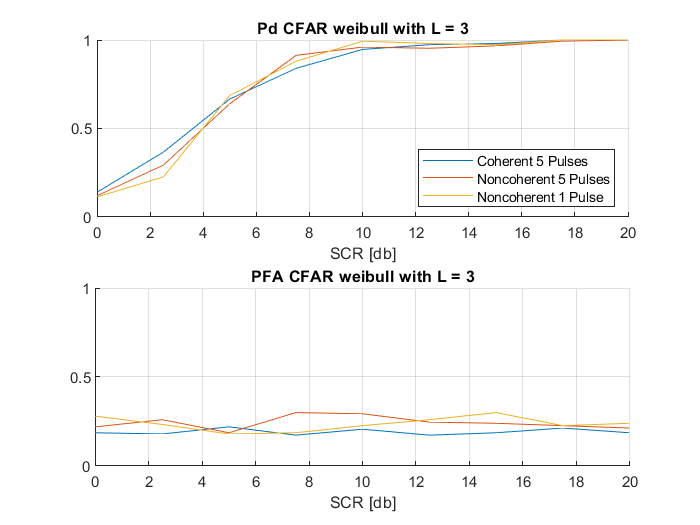

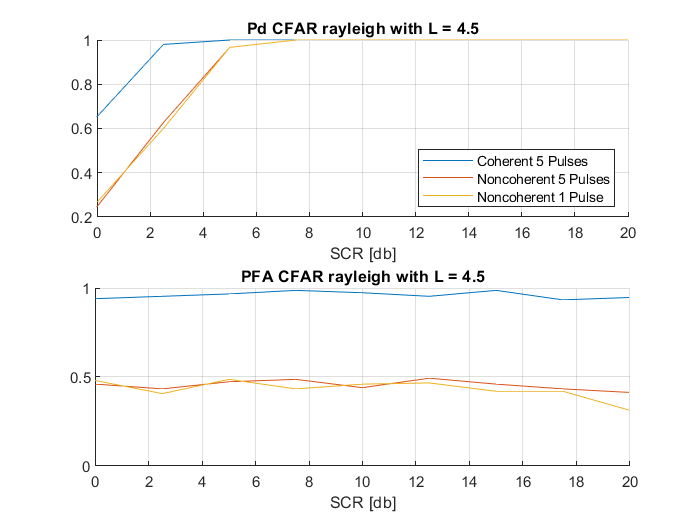

    aspect = [3 1 1];

    figure
    subplot(2,1,1)
    pbaspect(aspect)
    grid on
    hold on
    plot(SCR, Pd_coh)
    plot(SCR, Pd_ncoh)
    plot(SCR, Pd_none)
    xlabel('SCR [db]')
    title(strcat("Pd CFAR ", distrib(j), " with L = ", num2str( L(j) ) ) )
    legend('Coherent 5 Pulses', 'Noncoherent 5 Pulses', 'Noncoherent 1 Pulse', 'Location', 'southeast')


    subplot(2,1,2)
    pbaspect(aspect)
    hold on
    grid on
    plot(SCR, pfa_coh)
    plot(SCR, pfa_ncoh)
    plot(SCR, pfa_none)
    xlabel('SCR [db]')
    ylim([0 1])
    title(strcat("PFA CFAR ", distrib(j)," with L = ", num2str( L(j) ) ) )

## Em seguida, são apresentados os plots da variação dos limiares CFAR ao decorrer dos ranges, comparados com a entrada do filtro CFAR.

## A entrada do filtro CFAR foi definida como $\mathbf{s} = 10 \log_{10} \left[ 999 \times \frac{\mathbf{s} - \mathrm{min}(\mathbf{s})}{ \mathrm{max}(\mathbf{s}) - \mathrm{min}(\mathbf{s} )} + 1 \right]$.

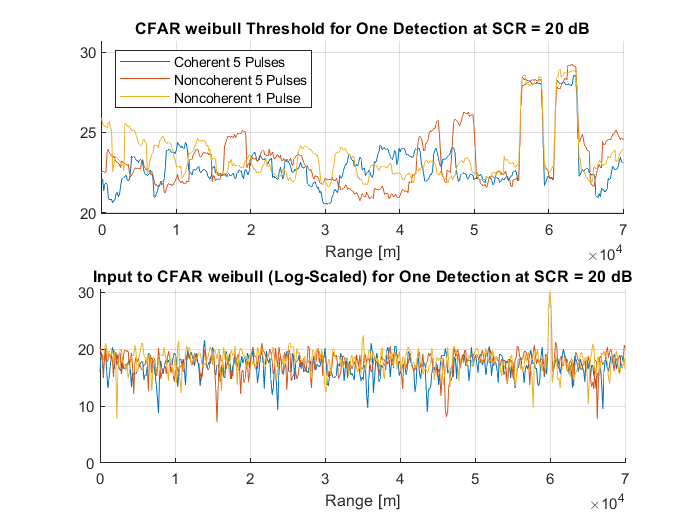

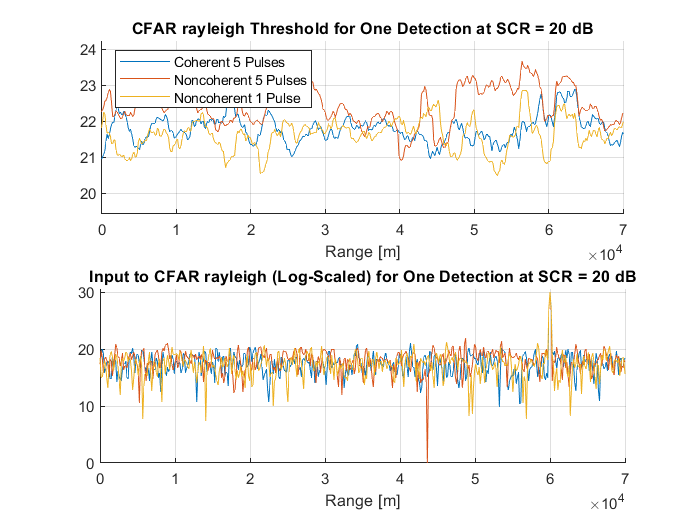

    figure 
    subplot(2,1,1)
    pbaspect(aspect)
    hold on
    grid on
    xlim( [0 7e4] )
    ylim( [ (1 - 0.025)*min( [ thresh_none(:,end); thresh_ncoh(:,end); thresh_coh(:,end) ] ) ...
        (1 + 0.025)*max([ thresh_none(:,end); thresh_ncoh(:,end); thresh_coh(:,end) ]) ])
    plot(rangegates, thresh_coh(:,end))
    plot(rangegates, thresh_ncoh(:,end))
    plot(rangegates, thresh_none(:,end))
    xlabel("Range [m]")
    title(strcat("CFAR ", distrib(j), " Threshold for One Detection at SCR = ", num2str( SCR(end) ), " dB" ) )
    legend("Coherent 5 Pulses", "Noncoherent 5 Pulses", "Noncoherent 1 Pulse", "Location", "northwest")

    subplot(2,1,2)
    pbaspect(aspect)
    hold on
    grid on
    xlim( [0 7e4] )
    ylim( [ (1 - 0.025)*min([signal_cfar_none(:,end); signal_cfar_ncoh(:,end); signal_cfar_coh(:,end)]) ...
        (1 + 0.025)*max([signal_cfar_none(:,end); signal_cfar_ncoh(:,end); signal_cfar_coh(:,end);]) ])
    plot(rangegates, signal_cfar_coh(:,end))
    plot(rangegates, signal_cfar_ncoh(:,end))
    plot(rangegates, signal_cfar_none(:,end))
    xlabel("Range [m]")
    title(strcat("Input to CFAR ", distrib(j), " (Log-Scaled) for One Detection at SCR = ", num2str( SCR(end) ), " dB" ) )

end